# PMSM state feedback control

h = 0.01;
z = tf('z', h);
H = (6.91*z^2 + 16.48*z - 17.87)/(z*(z^2 - 1.766*z + 0.7665))

H =
 
  6.91 z^2 + 16.48 z - 17.87
  --------------------------
  z^3 - 1.766 z^2 + 0.7665 z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



## State space model controllable form

Phi = [1.77, -0.775, 0; 1, 0, 0;0, 1, 0]

Phi =     1.7700   -0.7750         0
    1.0000         0         0
         0    1.0000         0


Gamma = [1;0;0]

Gamma =      1
     0
     0


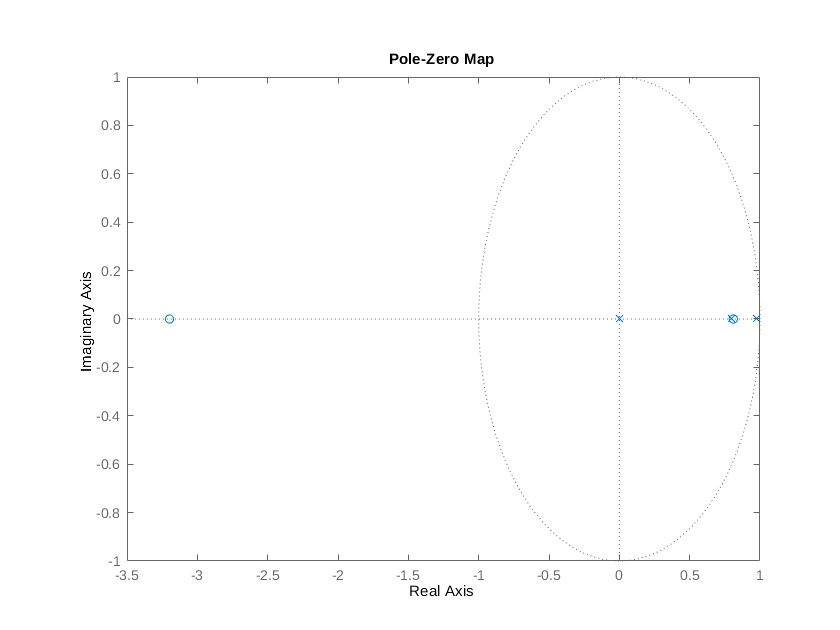

C = [6.91, 16.5, -17.9];
D = [0];
sys = ss(Phi, Gamma, C, D, h);
%Htest = tf(sys)
figure()
pzmap(sys)

zero(sys)

ans =    -3.1979
    0.8100


pole(sys)

ans =          0
    0.7943
    0.9757


## State feedback design


pd = [0.8+0.4i;0.8-0.4i;0];
L = acker(Phi, Gamma, pd)

L =     0.1700    0.0250         0


% Check
eig(Phi - Gamma*L)

ans =    0.0000 + 0.0000i
   0.8000 + 0.4000i
   0.8000 - 0.4000i



% Closed-loop system
sys_c = ss(Phi-Gamma*L, Gamma, C, D, h)

sys_c =
 
  A = 
         x1    x2    x3
   x1   1.6  -0.8     0
   x2     1     0     0
   x3     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1   6.91   16.5  -17.9
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



l0 = 1/dcgain(sys_c)

l0 = 0.0363

Phic = Phi - Gamma*L;
l0 = 1/(C*inv((eye(3)-Phic))*Gamma)

l0 = 0.0363

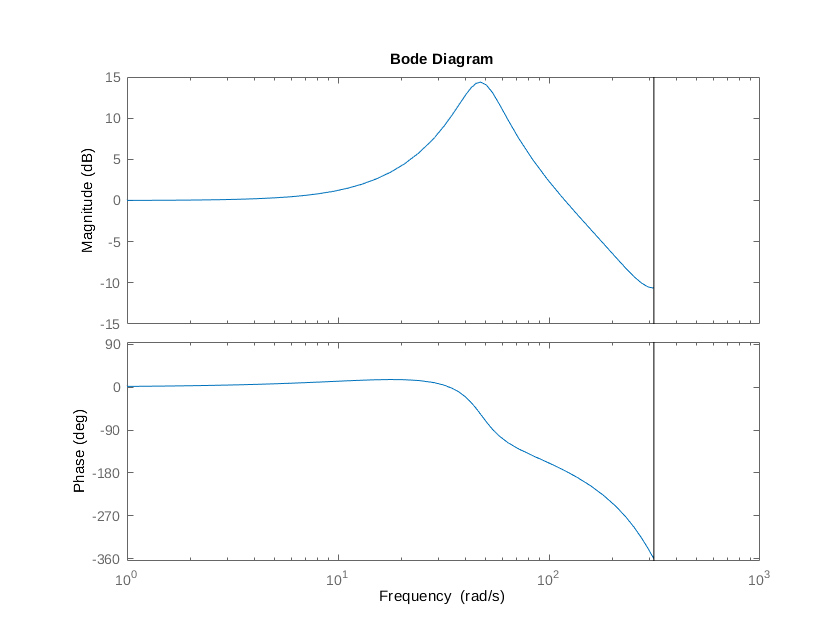


figure()
bode(l0*sys_c)

## Observer design

po = [0.3, 0.3, 0.3];
K = acker(Phi', C', po)'

K =     1.5655
    1.8895
    2.2975


% Check
eig(Phi - K*C)

ans =    0.3001 + 0.0000i
   0.3000 + 0.0000i
   0.3000 - 0.0000i
